# Pratik Ravikumar Sanghavi (2017AAPS0394G)

## Program Initialization

clc;
clear all;
close all;

## Generation of Sinusoidal Signal

% Amplitude
A=5;
%Frequency of signal
fm=70;
% Sampling Frequency
fs=1400;
% Duration of Signal
t=0:1/fs:1;
xn=A*sin(2*pi*fm*t);

## FFT Computation of Pure Sinusoidal Signal

N=700;
% frequency specification
f=(0:1:(floor(N/2)-1)).*fs/N;
%FFT of signal
Xk=fft(xn,N);
Xkssb=Xk(1:N/2);
Xkssb=Xkssb./(N/2);
%Magnitude specification
Xkssbm=abs(Xkssb);

## Generation of Plots for Pure Sinusoid

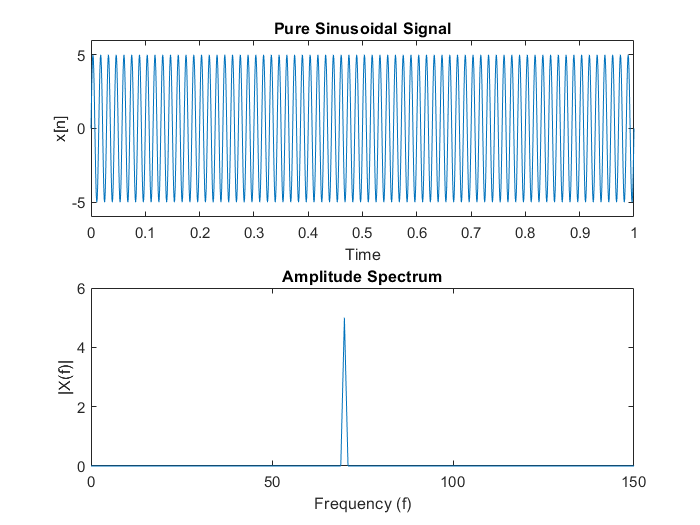

figure(1);
title('Signal Visualization in Time and Frequency Domain')

subplot(211);
plot(t,xn);
xlabel('Time');
ylabel('x[n]');
title('Pure Sinusoidal Signal');
axis([0 1 -6 6]);

subplot(212);
plot(f,Xkssbm);
title('Amplitude Spectrum');
xlabel('Frequency (f)');
ylabel('|X(f)|');
axis([0 150 0 6]);

## Impinging Noise onto Signal

% Generation of Noise
k=1.2;
nsig=k*randn(1,length(xn));
% Impinging noise
xnn=xn+nsig;

## FFT Computation of Signal with Noise

%FFT of signal
Xnk=fft(xnn,N);
Xnkssb=Xnk(1:N/2);
Xnkssb=Xnkssb./(N/2);
%Magnitude specification
Xnkssbm=abs(Xnkssb);

## Generation of plots for Signal with Noise

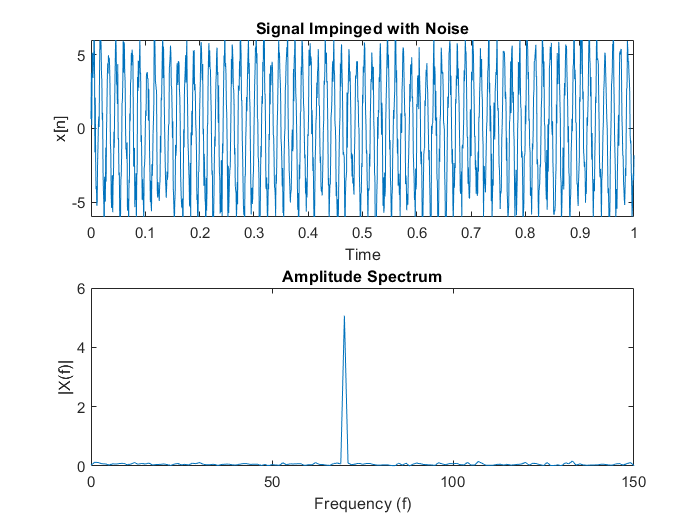

figure(2);
title('Signal with Noise Visualization in Time and Frequency Domain')

subplot(211);
plot(t,xnn);
xlabel('Time');
ylabel('x[n]');
title('Signal Impinged with Noise');
axis([0 1 -6 6]);

subplot(212);
plot(f,Xnkssbm);
title('Amplitude Spectrum');
xlabel('Frequency (f)');
ylabel('|X(f)|');
axis([0 150 0 6]);

## System Definition

M=12;
b=ones(1,M)./M;

## Generation of Filtered Output

yn=filter(b,1,xnn);

## FFT Computation of Filtered Output

%FFT of signal
Yk=fft(yn,N);
Ykssb=Yk(1:N/2);
Ykssb=Ykssb./(N/2);
%Magnitude specification
Ykssbm=abs(Ykssb);

## Generation of plots for Filtered Output

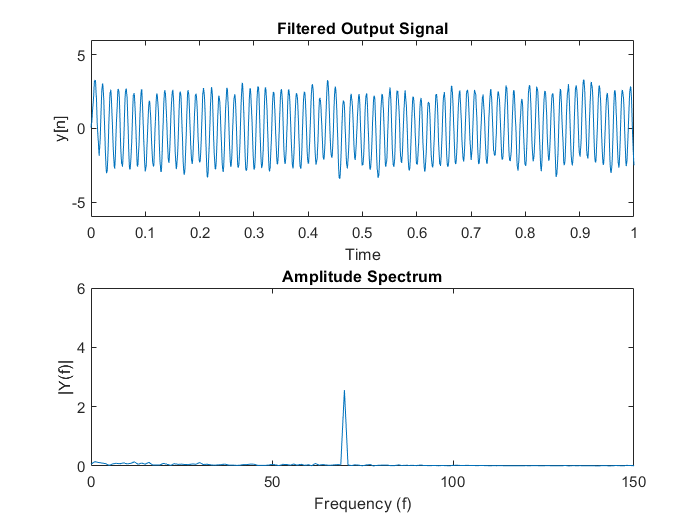

figure(3);
title('Filtered Output Signal Visualization in Time and Frequency Domain')

subplot(211);
plot(t,yn);
xlabel('Time');
ylabel('y[n]');
title('Filtered Output Signal');
axis([0 1 -6 6]);

subplot(212);
plot(f,Ykssbm);
title('Amplitude Spectrum');
xlabel('Frequency (f)');
ylabel('|Y(f)|');
axis([0 150 0 6]);